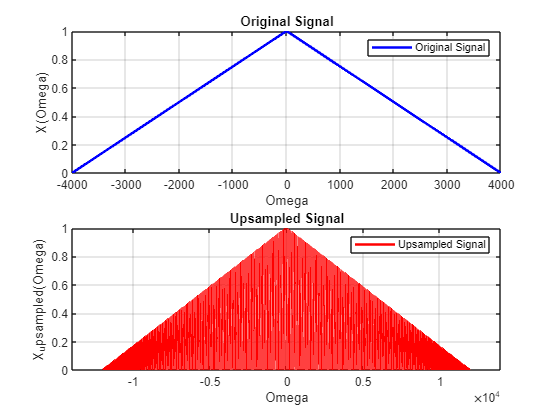

% Given parameters
Omega_N = 4000;  % Maximum frequency in Hz
M = 3;           % Downsampling factor
L = 2;           % Upsampling factor

% Calculate sampling period
Ts = 1 / Omega_N;

% Define the original signal X(Ω) as a triangular pulse (same as Exercise 2)
Omega = linspace(-Omega_N, Omega_N, 1000);
X_Omega = zeros(size(Omega));
X_Omega(Omega >= -Omega_N & Omega <= 0) = (Omega(Omega >= -Omega_N & Omega <= 0) + Omega_N) / Omega_N;
X_Omega(Omega > 0 & Omega <= Omega_N) = (Omega_N - Omega(Omega > 0 & Omega <= Omega_N)) / Omega_N;

% Perform downsampling (same as Exercise 2)
X_downsampled = X_Omega(1:M:end);
Omega_downsampled = Omega(1:M:end);

% Perform upsampling by inserting zeros
upsampled_length = length(X_downsampled) * L;
X_upsampled = zeros(1, upsampled_length);
X_upsampled(1:L:end) = X_downsampled;

% Upsample the Omega array accordingly
Omega_upsampled = linspace(-Omega_N, Omega_N, upsampled_length)*3;

% Plot the original and upsampled signals
figure;
subplot(2, 1, 1);
plot(Omega, X_Omega, 'b', 'LineWidth', 2);
title('Original Signal');
xlabel('Omega');
ylabel('X(Omega)');
grid on;
legend('Original Signal');

subplot(2, 1, 2);
plot(Omega_upsampled, X_upsampled, 'r', 'LineWidth', 2);
xlim([-14000 14000])
title('Upsampled Signal');
xlabel('Omega');
ylabel('X_upsampled(Omega)');
grid on;
legend('Upsampled Signal');